- Is this histogram wrong?

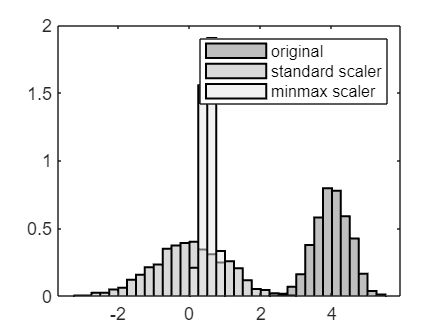

x = 0.5*randn(1000,1) + 4;
y = (x - mean(x)) / std(x);
z = (x - min(x)) / (max(x) - min(x));

figure;
histogram(x, 'BinMethod', 'Scott', 'Normalization', 'pdf', 'DisplayStyle', 'bar', 'EdgeColor', 'k', 'FaceColor', [0.5 0.5 0.5], 'FaceAlpha', 0.5, 'LineWidth', 1, 'BinWidth', 0.25, 'EdgeAlpha', 1, 'DisplayName', 'original');
hold on;
histogram(y, 'BinMethod', 'Scott', 'Normalization', 'pdf', 'DisplayStyle', 'bar', 'EdgeColor', 'k', 'FaceColor', [0.7 0.7 0.7], 'FaceAlpha', 0.5, 'LineWidth', 1, 'BinWidth', 0.25, 'EdgeAlpha', 1, 'DisplayName', 'standard scaler');
histogram(z, 'BinMethod', 'Scott', 'Normalization', 'pdf', 'DisplayStyle', 'bar', 'EdgeColor', 'k', 'FaceColor', [0.9 0.9 0.9], 'FaceAlpha', 0.5, 'LineWidth', 1, 'BinWidth', 0.25, 'EdgeAlpha', 1, 'DisplayName', 'minmax scaler');
legend('show');

2.

data = readtable('http://apmonitor.com/pds/uploads/Main/tclab_data6.txt');

% split into nonrandom train and test subsets (train: 80%, test: 20%)ta
idx= floor(0.8*height(data))

idx = 2880

dataTrain= data(1:idx,:);
dataTest= data(idx+1:end,:)

dataTest = 721×5 table
    Time    Q1    Q2     T1       T2  
    ____    __    __    _____    _____

    2880    0     0     59.25    27.02
    2881    0     0     59.22    27.02
    2882    0     0     58.99    27.02
    2883    0     0     58.93    27.02
    2884    0     0     58.93    27.02
    2885    0     0     58.64    27.02
    2886    0     0      58.6    27.02
    2887    0     0      58.6    27.02
    2888    0     0     58.28    27.02
    2889    0     0     58.25    27.02
    2890    0     0     57.96    27.02
    2891    0     0     57.96    27.02
    2892    0     0     57.64    27.02
    2893    0     0      57.6    27.02
    2894    0     0     57.31    27.02
    2895    0     0     57.28    27.02


%dataTrain = data(1:round(end*0.8-1),:);
%dataTest  = data(round(end*0.8):end,:);
disp (numel(dataTrain)/5)

        2880



disp (numel(dataTest)/5)

   721



3. 

% Standardize train data
s = zscore(dataTrain{:,2:end});
s_train = table(s);
disp(s_train)

                            s                         
    __________________________________________________

    -0.74829             0       -3.3534       -3.5218
    -0.74829             0       -3.3534       -3.5357
    -0.74829             0       -3.3534       -3.5078
    -0.74829             0       -3.3571       -3.5218
    -0.74829             0       -3.3571       -3.5496
    -0.74829             0       -3.3534       -3.5218
    -0.74829             0       -3.3571       -3.5218
    -0.74829             0       -3.3534       -3.5496
    -0.74829             0       -3.3534       -3.5357
    -0.74829             0       -3.3534       -3.5357
    -0.74829             0       -3.3534       -3.5496
    -0.74829             0       -3.3534       -3.5357
    -0.74829             0       -3.3534       -3.5357
    -0.74829             0       -3.3534       -3.5496
    -0.74829             0       -3.3534       -3.5496
    -0.74829             0    

4. unchecked (Standard scalar and Scalar Mean)

%nan_rows = any(isnan(s_train),2)
%A_no_nan = s_train(~nan_rows,:)
%dataTrain=A_no_nan

% Print scale
disp('a: ');

a: 


a=std(s)

a =     1.0000         0    1.0000    1.0000


disp(a);

    1.0000         0    1.0000    1.0000



Unrecognized function or variable 'StandardScalar'.

disp('Scaler mean')
% Print mean
b=mean(s)
disp('b: ');
disp(b);

5.   double check after 4, remove NANs

% Standardize test data
size(b)
size(a)
size(dataTest)
s_test = (dataTest{:,2:end} - b) ./ a;
s_test = table(s_test);

%notnull_rows = ~any(ismissing(s_test),2);
%result = s_test(notnull_rows, :);
%s_test = fillmissing(result, 'constant', 0);

disp(s_test)

6. unchecked

s_train_df = array2table(s_train, 'VariableNames', train.Properties.VariableNames);
s_test_df = array2table(s_test, 'VariableNames', test.Properties.VariableNames);



7. unchecked

% convert scaled values back to dataframe
s_train_df = pd.DataFrame(s_train, columns=train.columns.values);
s_test_df = pd.DataFrame(s_test, columns=test.columns.values);

8. unchecked, wrong?

Scaler multipliers
a: [0.11595824 0.11032197]
Scaler minimum
b: [18.85444444 31.69677778]

9. unchecked

x = s.inverse_transform(s_test);

10. unchecked

data = readtable('http://apmonitor.com/pds/uploads/Main/tclab_data6.txt');
data = table2timetable(data);
data.Time = datetime(data.Time,'InputFormat','yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
histogram(data.Variables,30,'Alpha',0.7,'DisplayStyle','stairs','LineWidth',1);
datetick('x','keeplimits');

11. unchecked

X = data;
X_scaled = (X-mean(X))./std(X);
histogram(X_scaled,10,'Alpha',0.7,'DisplayStyle','stairs','LineWidth',1);

12. unchecked

rng(0,'twister');
X = sdata;
p = 0.8;
cvp = cvpartition(size(X,1),'HoldOut',p);
X_train = X(training(cvp),:);
X_test = X(test(cvp),:);

% create neural network
hiddenLayerSize = [3 3];
net = fitnet(hiddenLayerSize,'trainlm');
[net,tr] = train(net,X_train(:,[1 2]),X_train(:,3));

% test neural network
X_test_predict = net(X_test(:,[1 2]));

% unscale data
X_test = s.inverse_transform(X_test);
X_test_predict = s.inverse_transform(X_test_predict');

% plot results
scatter(X_test(:,3),X_test_predict(:,3))
hold on
plot([15 28],[15 28],'r-')
xlabel('T2')
ylabel('T2p')
hold off
saveas(gcf,'results.png')

13. unchecked

data = readtable('http://apmonitor.com/pds/uploads/Main/tclab_data6.txt');

p = 0.8;
cvp = cvpartition(height(data),'HoldOut',p);
train = data(training(cvp),:);
test = data(test(cvp),:);

% train neural network
hiddenLayerSize = [3 3];
net = fitnet(hiddenLayerSize,'trainlm');
[net,tr] = train(net,table2array(train(:,[2 3])),table2array(train(:,4)));

% test neural network
test.T2p = predict(net,table2array(test(:,[2 3])))

% plot results
scatter(table2array(test(:,4)),table2array(test(:,5)))
hold on
plot([15 28],[15 28],'r-')
xlabel('T2')
ylabel('T2p')
hold off
